# Calibration ToF

## Import data

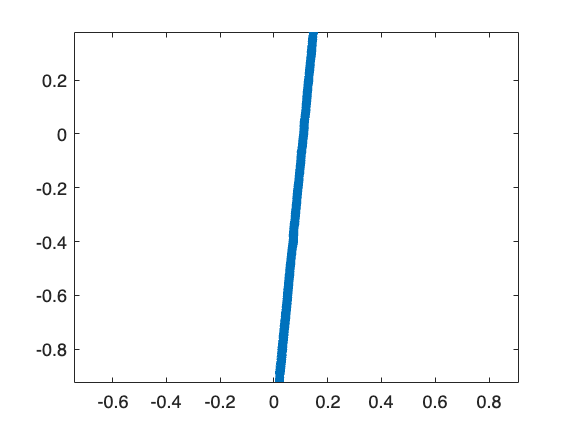

clc; clear; close all;

line = load("../trainingData/calib2_straight.mat");
GT_position = squeeze(line.out.GT_position.signals.values);
GT_rotation = squeeze(line.out.GT_rotation.signals.values);
GT_time = squeeze(line.out.GT_position.time);

ToF1_raw = squeeze(line.out.Sensor_ToF1.signals.values);
ToF2_raw = squeeze(line.out.Sensor_ToF2.signals.values);
ToF3_raw = squeeze(line.out.Sensor_ToF3.signals.values);
ToF_time = squeeze(line.out.Sensor_ToF1.time)';

figure;
plot(GT_position(:,1), GT_position(:,2), 'LineWidth', 5)
axis equal;

## Offset calculations for each of the Sensors

yaw   = quat2eul(GT_rotation, 'ZYX'); 
yaw   = unwrap(yaw(:,1));

GT_x = GT_position(:,1);
GT_y = GT_position(:,2);

% Wall positions in arena
x_wall_right = 1.2;
x_wall_left  = -1.2;
y_wall_front = 1.2;

% ToF2: Forward-Facing 
cost_fn2 = @(offset) ...
    sum((y_wall_front - (GT_y + offset(2)*cos(yaw) + offset(1)*sin(yaw)) - ToF2_raw(:,1)).^2);

offset2_0 = [0, 0];  % Initial guess
[ToF2_offset, ~] = fminsearch(cost_fn2, offset2_0);

% ToF 1 and ToF 3 (Side) Shared_params = [dx, dy] → ToF1 = [dx, dy], ToF3 = [-dx, dy]
cost_fn_shared = @(offset) sum((x_wall_right - (GT_x + offset(1)*cos(yaw) - offset(2)*sin(yaw)) - ToF1_raw(:,1)).^2) + ... 
                           sum((GT_x - offset(1)*cos(yaw) - offset(2)*sin(yaw) - x_wall_left - ToF3_raw(:,1)).^2);

offset_0 = [0.1, 0.05];
[shared_offset, ~] = fminsearch(cost_fn_shared, offset_0);

ToF1_offset = [ shared_offset(1),  shared_offset(2)];
ToF3_offset = [-shared_offset(1), shared_offset(2)];

% Save results
calibrationToF.ToF1 = ToF1_offset;
calibrationToF.ToF2 = ToF2_offset;
calibrationToF.ToF2 = ToF3_offset;

save("calibrationToF.mat", "calibrationToF")

% Print Results 
fprintf("Estimated Sensor Offsets from Robot Center:\n");

Estimated Sensor Offsets from Robot Center:


fprintf("ToF1 (Right): dx = %.4f m, dy = %.4f m\n", ToF1_offset(1), ToF1_offset(2));

ToF1 (Right): dx = -0.3766 m, dy = 0.0231 m


fprintf("ToF2 (Front): dx = %.4f m, dy = %.4f m\n", ToF2_offset(1), ToF2_offset(2));

ToF2 (Front): dx = -0.2667 m, dy = 0.0422 m


fprintf("ToF3 (Left):  dx = %.4f m, dy = %.4f m\n", ToF3_offset(1), ToF3_offset(2));

ToF3 (Left):  dx = 0.3766 m, dy = 0.0231 m


## Old Approach

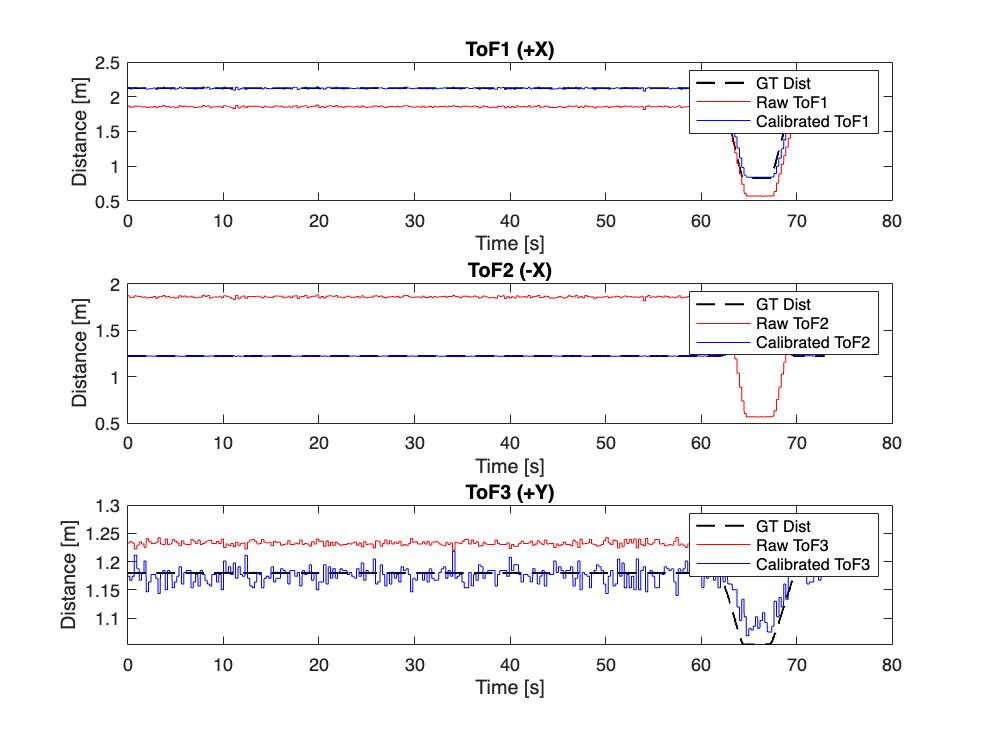

ToF1_raw = ToF2_raw(1,:);
ToF2_raw = ToF1_raw(1,:);
ToF3_raw = ToF3_raw(1,:);
x_wall_right = 1.2;  % wall in +x direction (right)
x_wall_left  = -1.2;  % wall in -x direction (left)
y_wall_front  = 1.2;  % wall in +y direction
y_wall_back  = -1.2;  % wall in -y direction

% Calculate expected true distances for each ToF
GT_x = GT_position(:,1);
GT_y = GT_position(:,2);

expected_ToF1 = abs(y_wall_front - GT_y);  % ToF1 faces forward (+y)
expected_ToF2 = abs(GT_x - x_wall_left);   % ToF2 faces left (-x)
expected_ToF3 = abs(x_wall_right - GT_x);   % ToF3 faces right (+x)

%% Calibrate using linear regression
% You can change the degree of fit for better accuracy

% Linear calibration
p1 = polyfit(ToF1_raw, expected_ToF1, 3);

%Bias only calibration, as the data is not varied enough
p2 = polyfit(ToF2_raw, expected_ToF2, 1);
p3 = polyfit(ToF3_raw, expected_ToF3, 1);

% Apply calibration
ToF1_cal = polyval(p1, ToF1_raw);
ToF2_cal = polyval(p2, ToF2_raw);
ToF3_cal = polyval(p3, ToF3_raw);

%% Plot and compare
figure;
subplot(3,1,1);
plot(ToF_time, expected_ToF1, 'k--', 'LineWidth', 1.2); hold on;
plot(ToF_time, ToF1_raw, 'r'); 
plot(ToF_time, ToF1_cal, 'b');
legend('GT Dist', 'Raw ToF1', 'Calibrated ToF1');
xlabel('Time [s]'); ylabel('Distance [m]'); title('ToF1 (+X)');

subplot(3,1,2);
plot(ToF_time, expected_ToF2, 'k--', 'LineWidth', 1.2); hold on;
plot(ToF_time, ToF2_raw, 'r'); 
plot(ToF_time, ToF2_cal, 'b');
legend('GT Dist', 'Raw ToF2', 'Calibrated ToF2');
xlabel('Time [s]'); ylabel('Distance [m]'); title('ToF2 (-X)');

subplot(3,1,3);
plot(ToF_time, expected_ToF3, 'k--', 'LineWidth', 1.2); hold on;
plot(ToF_time, ToF3_raw, 'r'); 
plot(ToF_time, ToF3_cal, 'b');
legend('GT Dist', 'Raw ToF3', 'Calibrated ToF3');
xlabel('Time [s]'); ylabel('Distance [m]'); title('ToF3 (+Y)');